clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
addpath('E:\PhD\meetings_n_conf\2022\wk 14\Colormaps\Colormaps (5)\Colormaps')
S =data_list_adamantane;

## import the data if already converted to ANA

for f = 1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata);
    data_converted(f) = macro.convert(data_corrected, mdata);
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv(f) = (S(f).photon);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.54513


Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


The Scaling factor is 0.48224


## Plot AES

figure; hold on
for i=1:length(S)
    [centres, electron_KE] = get_AES(data_converted(i), data_stats(i));
end
legend(num2str(hv')); box on
% xline([245 249 252 256 264 270] ,'LineStyle',':'); 
xline(256.3,'LineStyle',':'); xline(263.2,'LineStyle',':');
% xline(252,'LineStyle',':'); xline(256,'LineStyle',':');
% xline(264,'LineStyle',':'); xline(270,'LineStyle',':');


## Plot ES specific Ion TOF and m2q

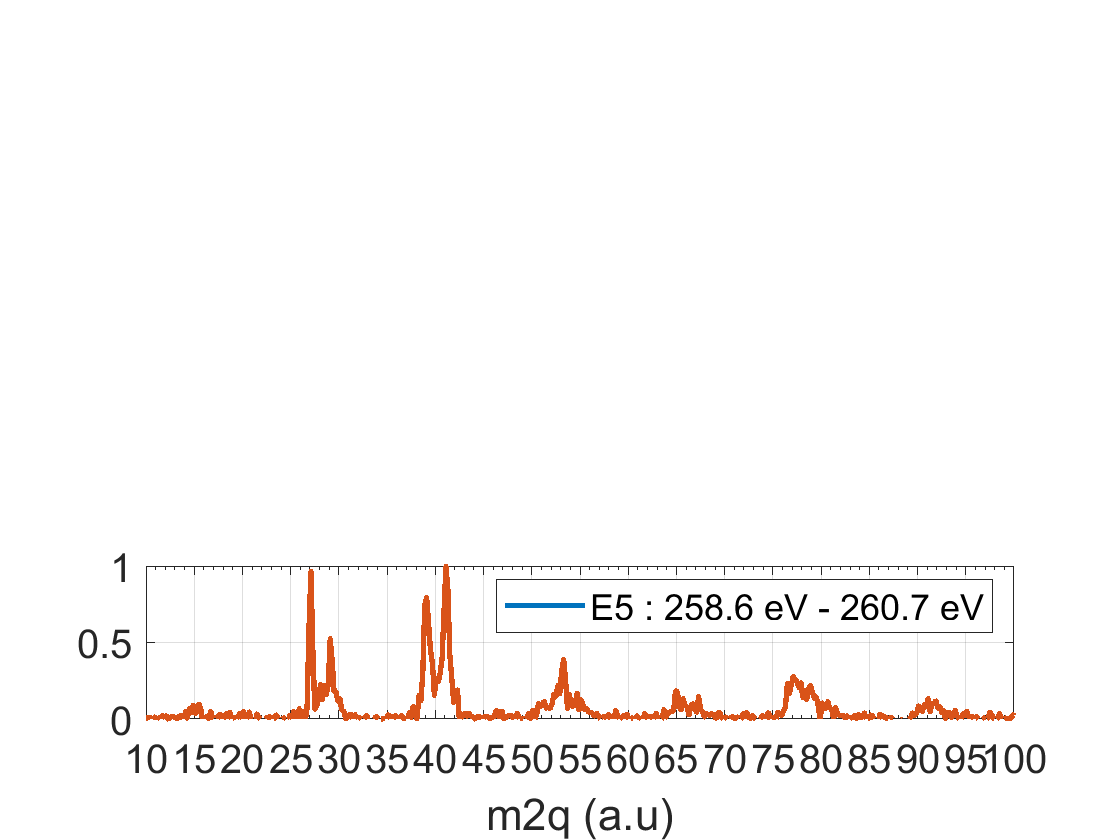

m2q_range =[0 ; 140];
% figure; hold on
% es_range = [255.1;258.4];
% es_range = [261.5;264.1];

es_range = [250.5;254.4];
es_range = [254.9;257.1];
es_range = [258.6;260.7];


for i=length(S)%1:2%%:3
    [TetEI_x_m2q,Xcenters,Ycenters] = get_pepico_m2q(data_converted(i), data_stats(i),m2q_range);
    idx = Xcenters>es_range(1) & Xcenters<es_range(2);
    m2q = sum(TetEI_x_m2q(idx,:));
%     subplot1 = subplot(2,1,i); 
    subplot1 = subplot(3,1,3); 

    hold on
    plot(Ycenters,m2q./max(m2q), 'DisplayName',sprintf('hv =%.1f eV',hv(i)),'LineWidth',2)%
    legend(sprintf('E5 : %.1f eV - %.1f eV', es_range(1),es_range(2)))
    ylim([0 1])
%     for cc =1:10
%         xline(12*cc);
%     end

% Uncomment the following line to preserve the X-limits of the axes
xlim(subplot1,[10 100]);
% Uncomment the following line to preserve the Y-limits of the axes
ylim(subplot1,[0 1]);
box(subplot1,'on');
% Set the remaining axes properties
set(subplot1,'FontSize',15,'XGrid','on','XMinorTick','on','XTick',...
    [10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100],'YGrid','on');
% Create legend
legend(subplot1,'show');
end
% sgtitle(sprintf('E1 : %.1f eV - %.1f eV', es_range(1),es_range(2)))
xlabel('m2q (a.u)')

## TOF and M2Q spectra All ions

%


b_r =zeros(17,3);
figure; hold all
for i=2%length(S)
      subplot(length(S),1,i)
%     [Tet_tof,Tet_tof_error] = plot_mult_ion_tof(data_converted(i), data_stats(i), 1);
    [Bincenters,Tet_tof,Tet_tof_error] = plot_ion_tof(data_converted(i), data_stats(i));
%     [Bincenters,Tet_m2q,Tet_m2q_error] = plot_ion_m2q(data_converted(i), data_stats(i));
%     [Fragment,b_r(:,i)] = get_br(data_converted(i), data_stats(i), mdata)
%     legend(num2str(hv(i)))
end
% ylim([0 1])
% for kk =1:10
%     xline(12*(kk),'--');
% end
% T = table(hv, Fragment,b_r)
% T = table(Bincenters', Tet_tof', 'VariableNames', { 'Bincenters', 'tof'} )
% writetable(T, 'MyFile.txt')

## ION Kinetic energy One ion events

figure;
m2q_range1 = get_m2q_range(data_converted(1), data_stats(1))
% m2q_range2 = get_m2q_range(data_converted(1), data_stats(1))
% m2q_range3 = get_m2q_range(data_converted(1), data_stats(1))

% figure; hold all
% for i=1:3
%     subplot(3,1,i)
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range1);
%     hold on
% %     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range2);
% %     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range3);
%     title(num2str(hv(i)))
%     legend
% end

figure; hold all
m2q = 65;
for i=1:3
    subplot(3,1,i)
    [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q);
    hold on
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range2);
%     [Tet_ke,Tet_ke_error] = plot_ion_ker_c1(data_converted(i), data_stats(i),'direct_input',m2q_range3);
    title(num2str(hv(i)))
    legend
end


% ylim([0 1])

% figure
% [Tet_ke,Tet_ke_error] = plot_ion_ker(data_converted, data_stats,'m2q_label');

## Load ROI

c1 = 3;  h1 =3; c2= 4; h2= 3;
m2q_1 = 12*c1+h1; m2q_2 = 12*c2+h2;
filename= sprintf('c%ih%i_c%ih%i',c1,h1,c2,h2);
path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi\';
load([path,filename,'.mat'],'roi');

## ION Kinetic energy Two ion events

figure
plot_signal=struct();
% plot_signal.hit.data_pointer = 'data_converted.h.det2.KER';
% plot_signal.hit.label = 'Ion ke (eV)';%dp_{norm}
% plot_signal.Binsize =10; plot_signal.Range =[0, 400]; 
plot_signal.Binsize =0.3; plot_signal.Range =[0, 6]; 

plot_signal.event.data_pointer = 'data_converted.e.det2.KER_sum';
plot_signal.event.label = 'Ion KER (eV)';%p_{1z} + p_{2z}
plot.epicea.plot_ion_c2(data_converted(3), data_stats(3),roi,plot_signal,m2q_1,m2q_2)
legend(filename)
% plot_ion_ker_c2(data_converted(3), data_stats(3),roi)
% plot_ion_p_c2(data_converted(3), data_stats(3),mdata,m2q_1,m2q_2)
% plot_ion_psum_c2(data_converted(3), data_stats(3),mdata,m2q_1,m2q_2)

## PIPIC-O

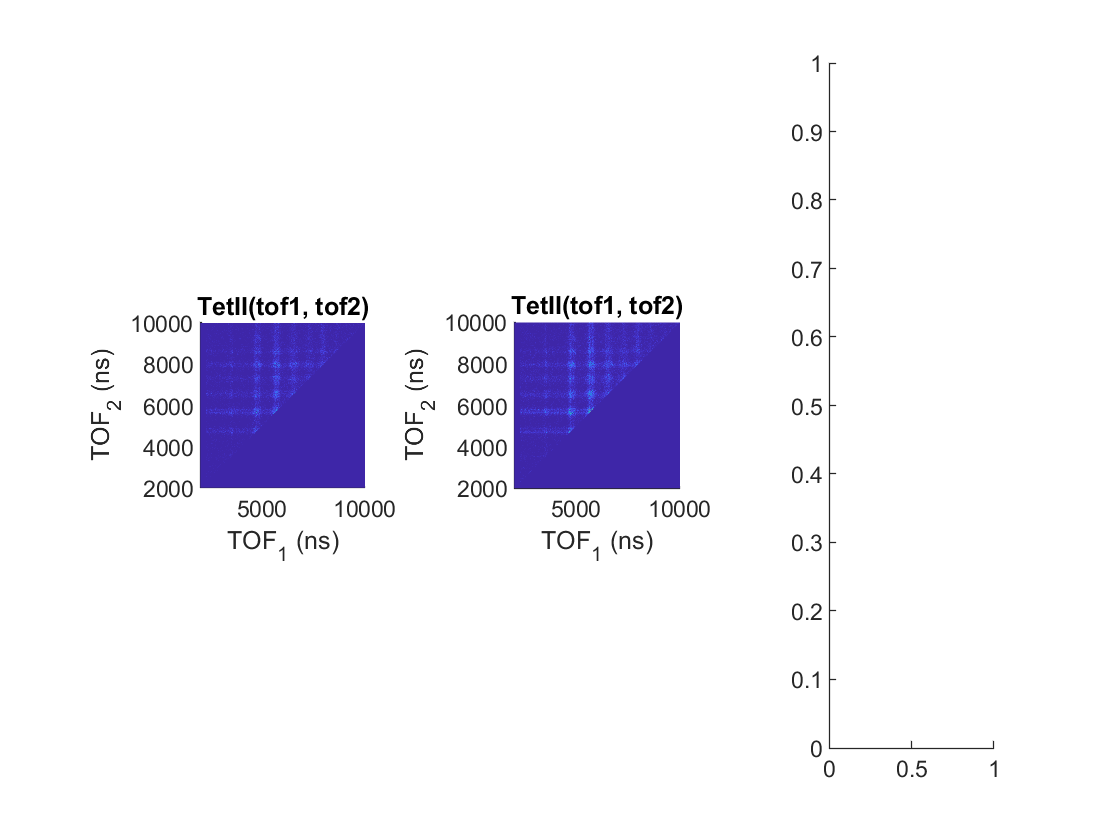

Index exceeds the number of array elements (2).

figure; hold on
for i=1:3
    subplot(1,3,i)
    [Tet_tof2] = plot_pipico(data_converted(i), data_stats(i));
end

## PIPICO (ES FILTERED)

figure; hold on
es_range = [241;243.5];
for i=1:3
    subplot(1,3,i)
    [data_stats_es_filt(i)] =get_data_stats_es_filt(data_converted(i),es_range);
    [Tet_tof2] = plot_pipico_es_filt(data_converted(i), data_stats_es_filt(i),es_range);
    title([num2str(hv(i)), ' eV'])
end
sgtitle(sprintf('Region 0 : %.0f eV - %.1f eV', es_range(1),es_range(2)))

## PEPICO

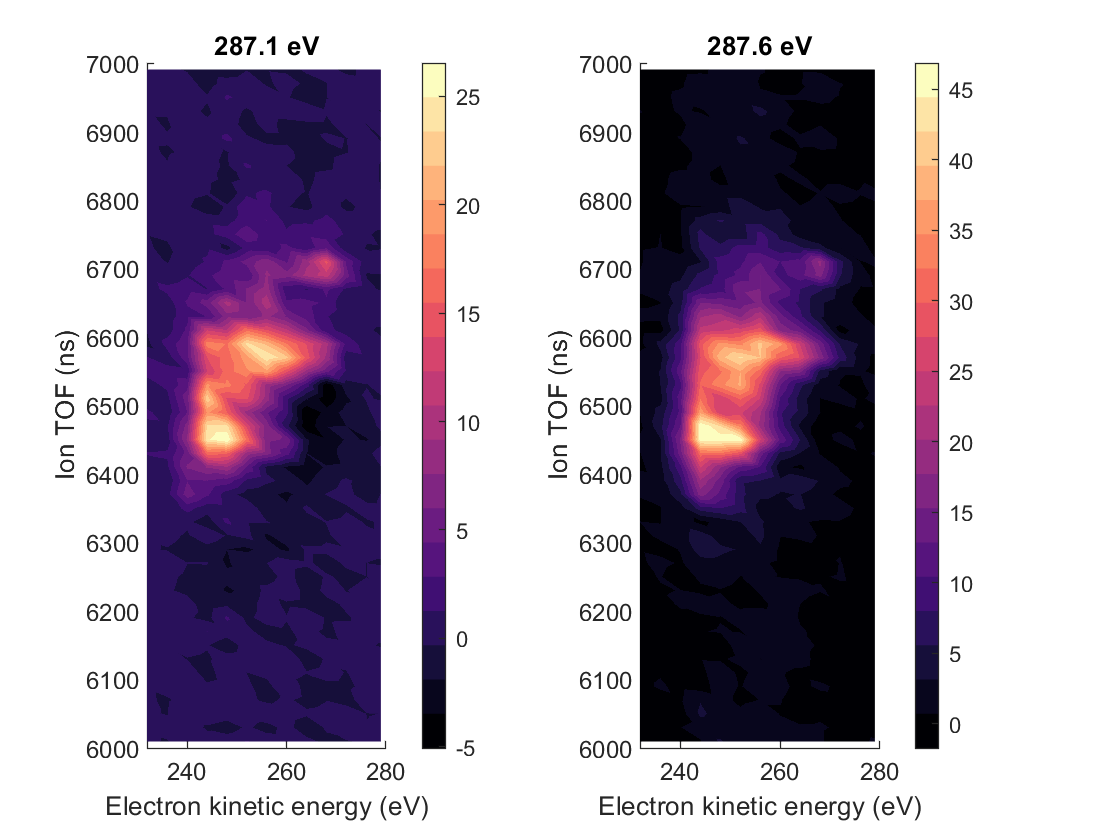

tof_range =[6000 ; 7000];
% tof_range =[4500 ; 5000];
figure%(11); %hAxes(1) =subplot(1,3,1); hAxes(2) =subplot(1,3,2);hAxes(3)  =subplot(1,3,3);
for i=1:2
    subplot(1,2,i)
     [TetEI_x_tof,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),tof_range);
    title([num2str(hv(i)), ' eV'])
%     AES_1 = sum(TetEI_x_tof,2);
%     plot(Xcenters,AES_1)
end

## Slices of PEPICO

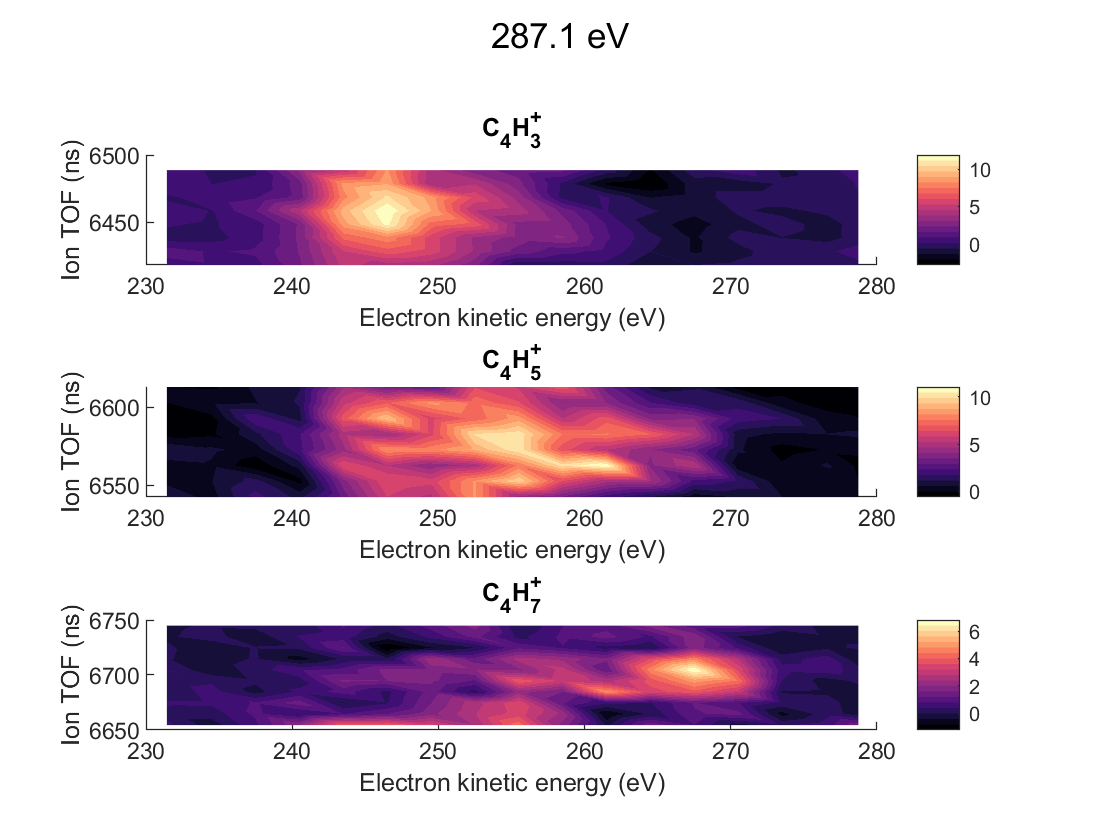

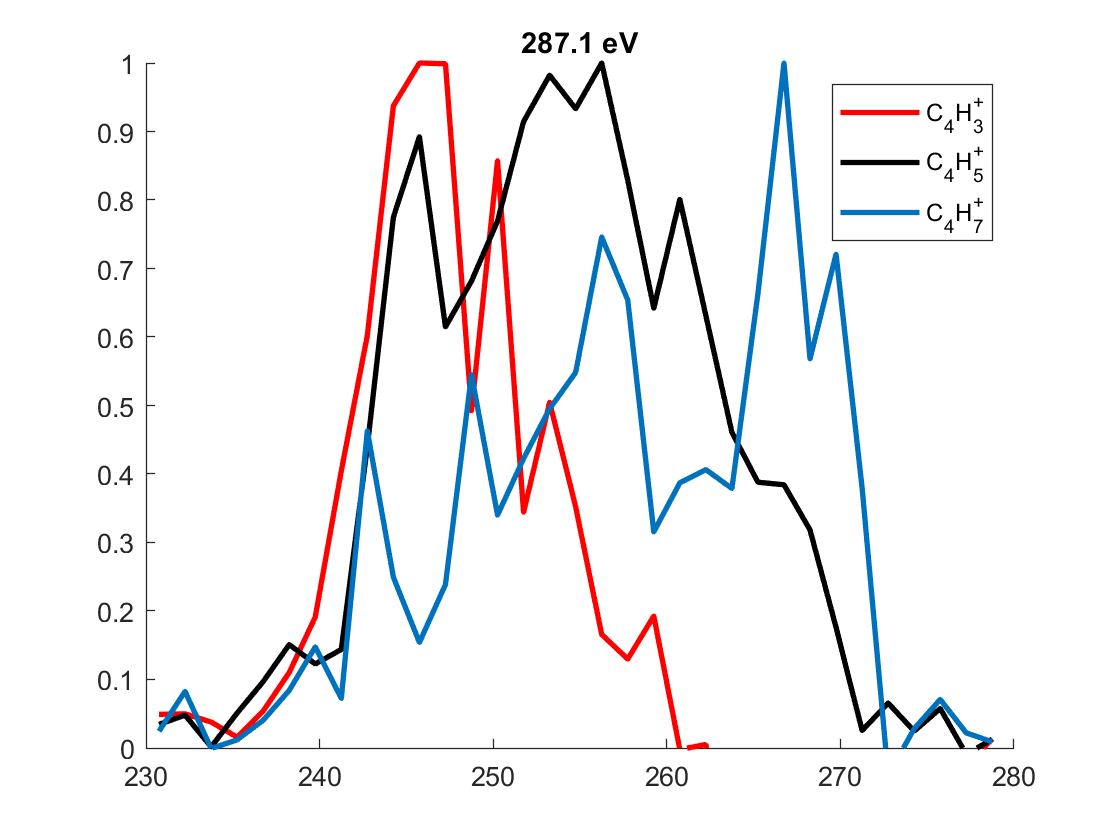

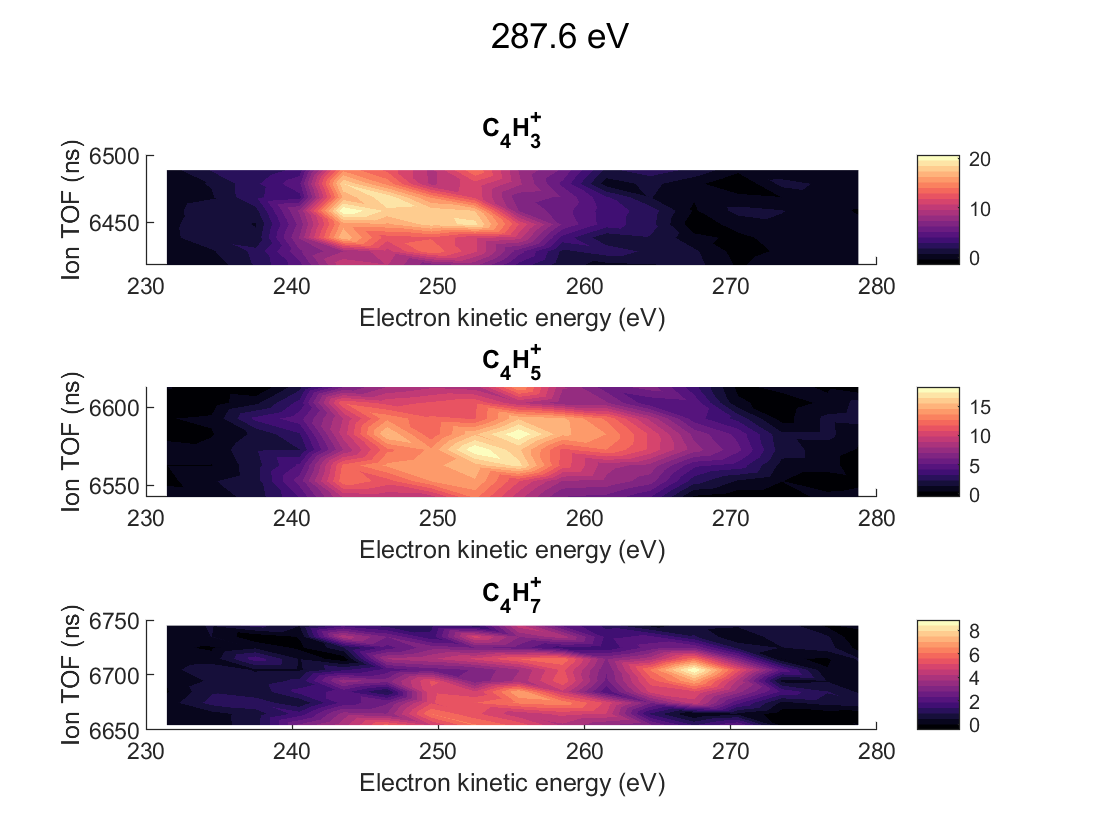

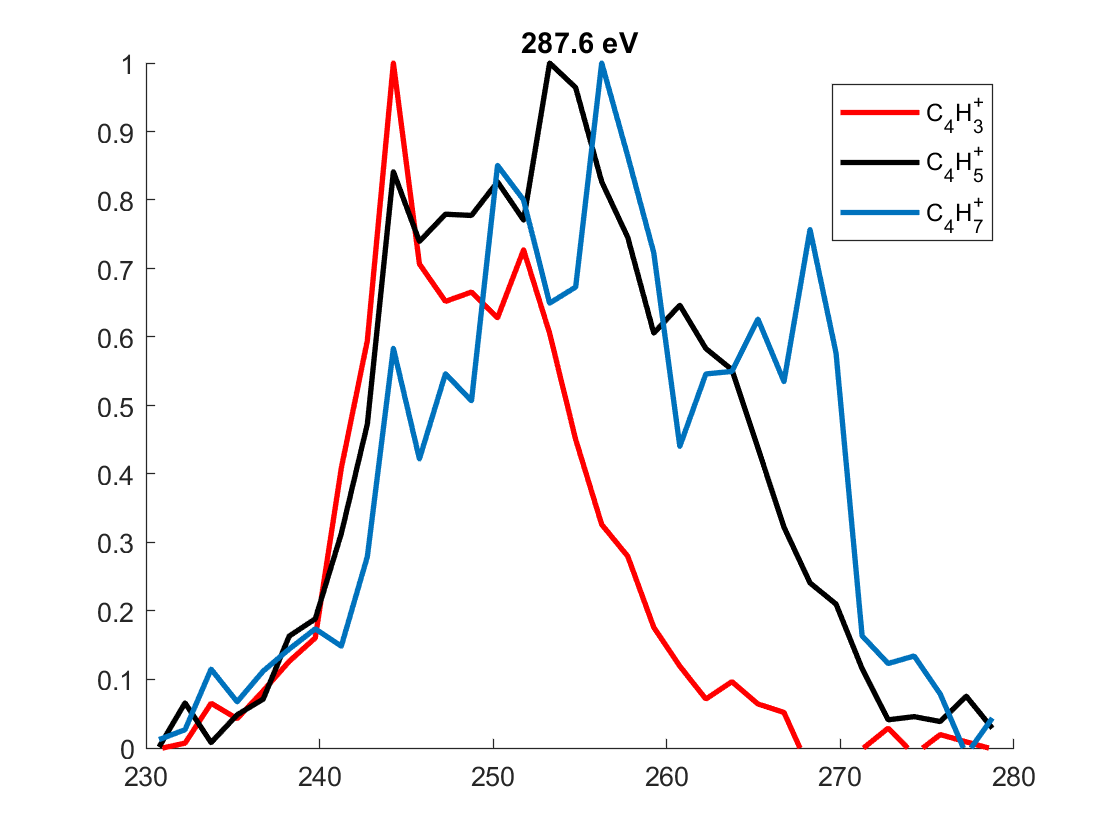

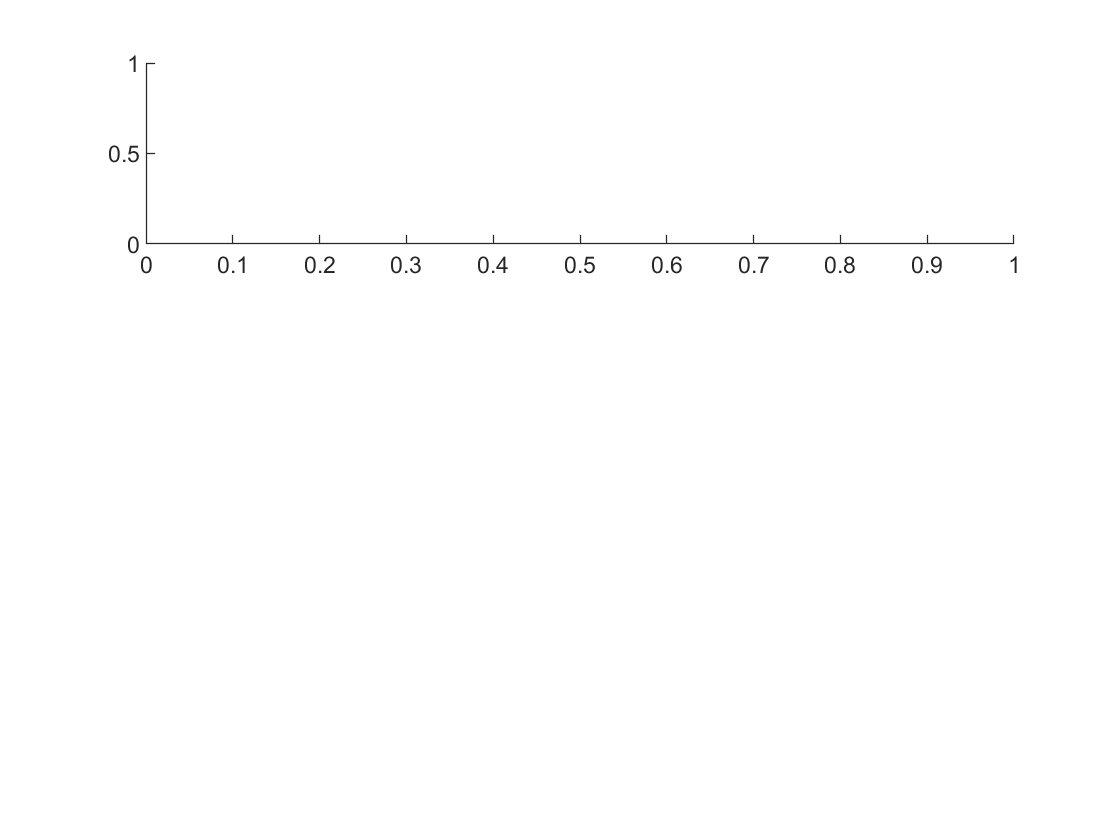

Index exceeds the number of array elements (2).

C1=4; H1=3; H2=5; H3 =7;
m2q_1 = 12*C1+1*H1; m2q_2 = 12*C1+1*H2;  m2q_3 = 12*C1+1*H3; 
label1 =sprintf('C_%dH_{%d}^+', C1,H1);label2 =sprintf('C_%dH_{%d}^+', C1,H2); label3 =sprintf('C_%dH_{%d}^+', C1,H3);
tof1 = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof2 = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof3 = convert.m2q_2_TOF(m2q_3,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
for i=1:3
    figure
    subplot(3,1,1);
    [TetEI_x_tof1,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof1-40;tof1+40]);
     title(label1)
     subplot(3,1,2);
    [TetEI_x_tof2,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof2-40;tof2+40 ]);
    title(label2)
    subplot(3,1,3);
    [TetEI_x_tof3,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof3-50;tof3+50 ]);
    title(label3)
    sgtitle([num2str(hv(i)), ' eV'])
    y1 =sum(TetEI_x_tof1, 2);
    y2 =sum(TetEI_x_tof2, 2);
    y3 =sum(TetEI_x_tof3, 2);
% tof_centers = Ycenters;%Yedges(1:end-1) + diff(Yedges) / 2; %tof values
    energy_val = Xcenters;%Xedges(1:end-1) + diff(Xedges) / 2;

    figure;%subplot(3,1,i); 
    hold on
    title([num2str(hv(i)), ' eV'])
    
%     scatter(energy_val,y1./max(y1),'DisplayName',label1,'MarkerFaceAlpha', 0.5, 'MarkerFaceColor','r'); hold on
%     scatter(energy_val,y2./max(y2),'DisplayName',label2,'MarkerFaceAlpha', 0.5, 'MarkerFaceColor','k'); hold on
    
%     energy_val1 = imresize(energy_val,0.75);
%     y1 = imresize(y1,0.75);
%     energy_val2 = imresize(energy_val,0.5);
%     y2 = imresize(y2,0.5);
    plot(energy_val,y1./max(y1),'r','DisplayName',label1,'LineWidth', 2); hold on
    plot(energy_val,y2./max(y2),'k','DisplayName',label2,'LineWidth', 2); hold on
    plot(energy_val,y3./max(y3),'DisplayName',label3,'LineWidth', 2); 
    ylim([0 1])
%      plot(energy_val,y1,'DisplayName',label1,'LineWidth', 2); hold on
%      plot(energy_val,y2,'DisplayName',label2,'LineWidth', 2); hold on
%     plot(energy_val,y3,'DisplayName',label3,'LineWidth', 2);  
    
    legend 
    
    
end

%  